clear
clc
close all

#### Reading the audio file

[signal,Fs] = audioread('listen-to-the-ancient-egyptions-tv .wav');

# `Psychoacoustic Model `

# `Computing SPL`

### Signal Spectrum after FFT

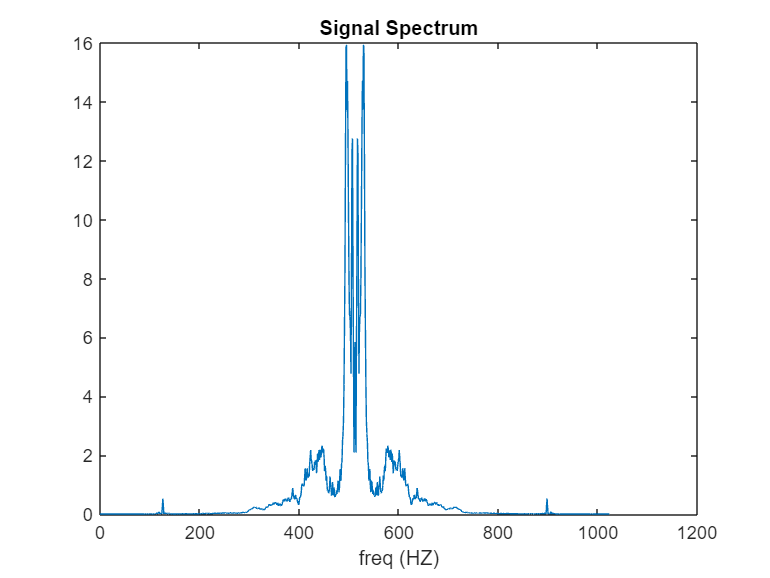

X = load('Signal_Spectrum.mat');
Signal_Spectrum = (X.Signal_Spectrum);
n = 0:length(Signal_Spectrum)-1;
plot(n,Signal_Spectrum)
xlabel('freq (HZ)')
title('Signal Spectrum')

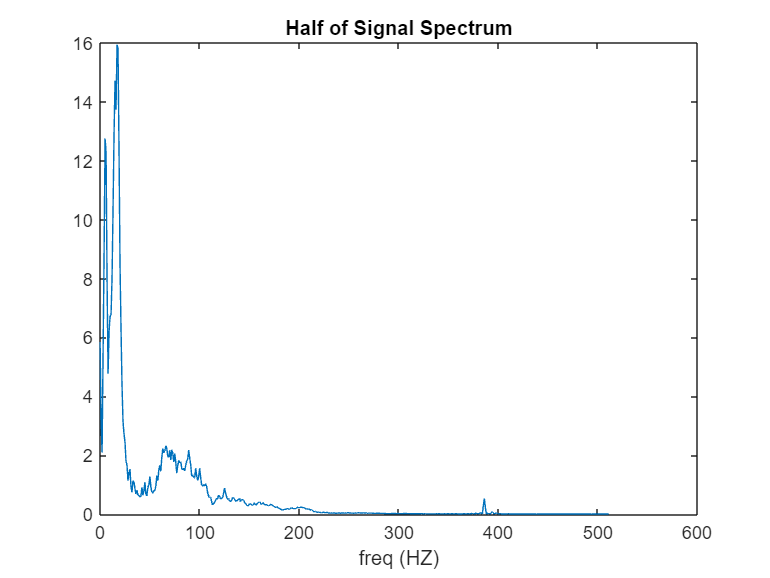

half_spectrum = X.Signal_Spectrum(513:end);
n = 0:length(half_spectrum)-1;

plot(n,half_spectrum)
xlabel('freq (HZ)')
title('Half of Signal Spectrum')

N = 1024;
f_vector = linspace(-Fs/2,Fs/2,N);
half_freq = f_vector(N/2+1:end);

### SPLs computing and evaluating

Lk = Lk_fn(N,half_spectrum)

Lk =    61.4100   56.0346   52.4889   60.8505   65.0221   68.1871   67.8572   64.0279   59.6446   61.9208   62.5920   62.7029   64.1634   66.3708   68.2824   69.4292   68.8269   70.1209   70.0547   67.9199   64.6587   62.0976   58.9225   56.0485   54.7868   53.8726   51.1547   50.5573   47.1825   48.9046   49.7552   45.6072   43.4762   47.1908   46.9903   44.7957   42.7806   44.2815   42.3369   42.1767   41.4054   41.8385   45.2982   42.2413   44.0697   46.8267   42.5260   41.9356   45.3011   46.0320


q_threshold = threshold_in_quiet(half_freq)

q_threshold =   127.5332   52.9506   35.1831   26.8762   21.9777   18.7146   16.3701   14.5959   13.2017   12.0742   11.1414   10.3555    9.6833    9.1008    8.5907    8.1397    7.7376    7.3766    7.0503    6.7537    6.4826    6.2337    6.0040    5.7913    5.5936    5.4090    5.2363    5.0740    4.9211    4.7767    4.6398    4.5097    4.3858    4.2675    4.1542    4.0455    3.9408    3.8400    3.7424    3.6479    3.5562    3.4669    3.3798    3.2947    3.2113    3.1294    3.0489    2.9695    2.8911    2.8136


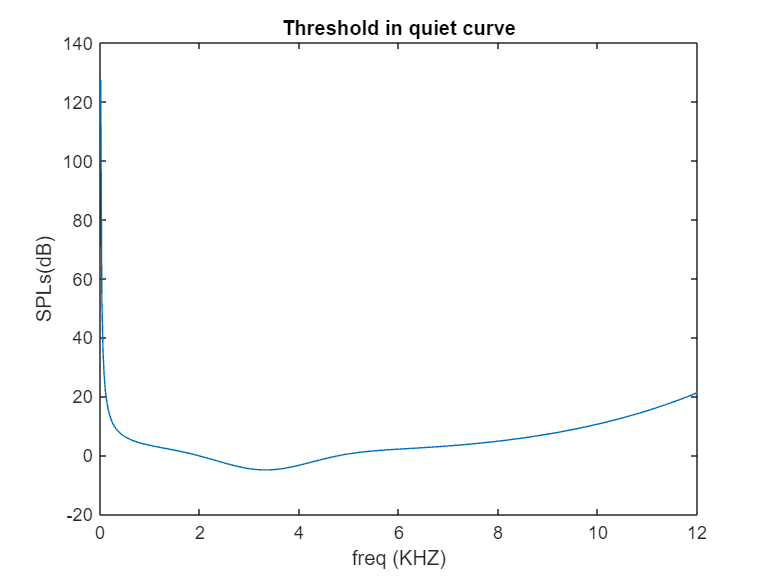


plot(half_freq/1000,q_threshold);
title('Threshold in quiet curve')
xlabel('freq (KHZ)')
ylabel('SPLs(dB)')

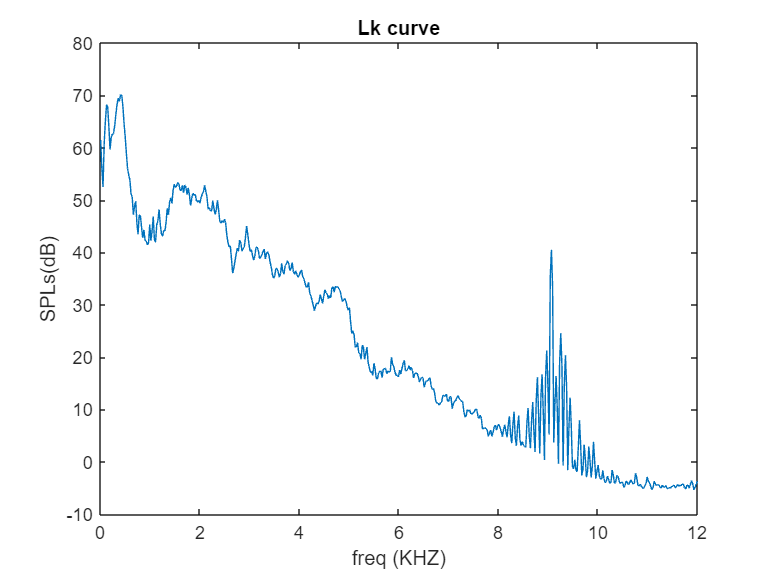

plot(half_freq/1000,Lk);
title('Lk curve')
xlabel('freq (KHZ)')
ylabel('SPLs(dB)')

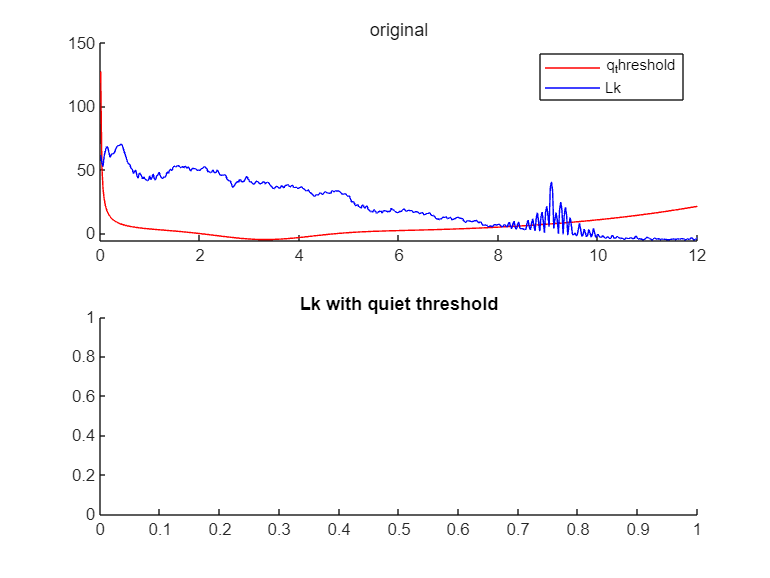


subplot(2,1,2);
title('Lk with quiet threshold');

subplot(2,1,1);

subtitle('original')
hold on
plot(half_freq/1000,q_threshold,Color='r');
plot(half_freq/1000,Lk,Color='b');
legend({'q_threshold','Lk'})
hold off

% set zeros to Lks that is less than the quite threshold
indices = q_threshold>Lk;
Lk(indices) = 0;

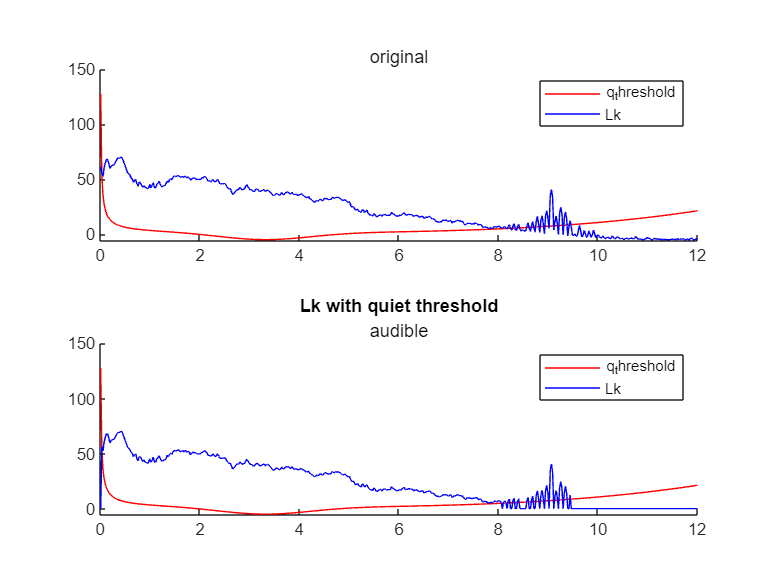

subplot(2,1,2);
subtitle('audible')
hold on
plot(half_freq/1000,q_threshold,Color='r');
plot(half_freq/1000,Lk,Color='b');
legend({'q_threshold','Lk'})
hold off

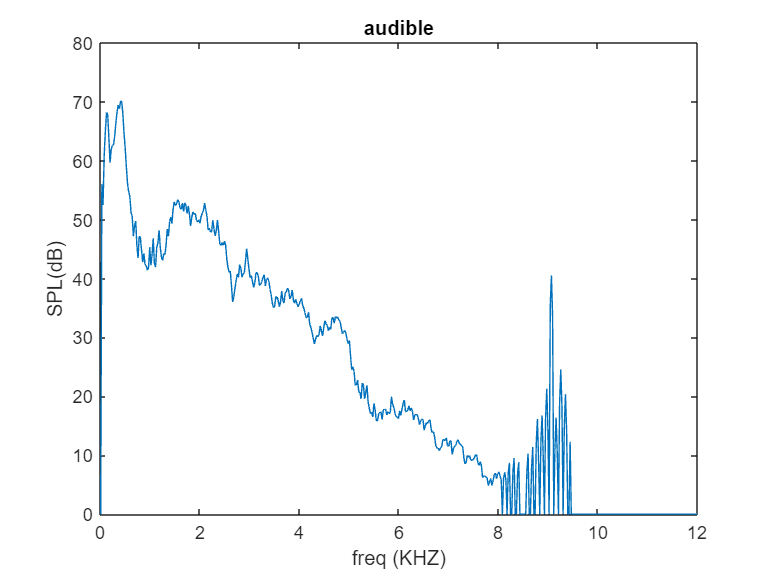

close all
plot(half_freq/1000,Lk);
title('audible')
xlabel('freq (KHZ)')
ylabel('SPL(dB)')

# `Psychoacoustic Model `

# Separation of Tonal & Non-Tonal Components

sub_num = 32;
SPL_matrix = vector2matrix(Lk,sub_num);
freq_matrix = vector2matrix(half_freq,sub_num);

for i = 1 : sub_num
    % the SPL and the freq of the i sub-band
    sub_band_SPL  = SPL_matrix(i,:);
    sub_band_freq = freq_matrix(i,:);
    % get the golobal and local maximas 
    [peakValues, peakIndices] = Find_maximas(sub_band_SPL);     % peakValues is the spl value
                                                                % peakIndices is its position                  
    % looping over the peaks in the sub-band
    for j = 1: length(peakValues)

        %index = peakIndices(j)+16*(i-1);
        masker_freq = sub_band_freq(peakIndices(j));
        masker_SPL  = peakValues(j);

        if masker_SPL ~= 0

            f2 = masking_threshold(masker_SPL,masker_freq);
            f2_SPL = threshold_in_quiet(f2);
            y_spl  = [masker_SPL f2_SPL];
            x_freq = [masker_freq f2];
            %p = spreading_fn(x,y);
            p = polyfit(x_freq,y_spl,1);
            delta = 1.5;
            p = p*delta;
            
            % looping over the affected part of the sub-band
            for k = peakIndices(j)+1 : 16
                if sub_band_freq(k) < f2
                    m_threshold = polyval(p,sub_band_freq(k));
                    if sub_band_SPL(k) < m_threshold
                        sub_band_SPL(k)=0;
                    end
                end
            end
            
        end
    end
    SPL_matrix(i,:) = sub_band_SPL;
end

Lk_after_masking = reshape(SPL_matrix.',1,[])

Lk_after_masking =          0   56.0346         0         0         0         0         0         0         0         0         0         0         0         0         0         0   68.8269   70.1209         0         0         0         0         0         0         0         0         0         0         0         0         0         0   43.4762   47.1908         0         0         0         0         0         0         0         0         0         0         0         0         0         0   45.3011   46.0320


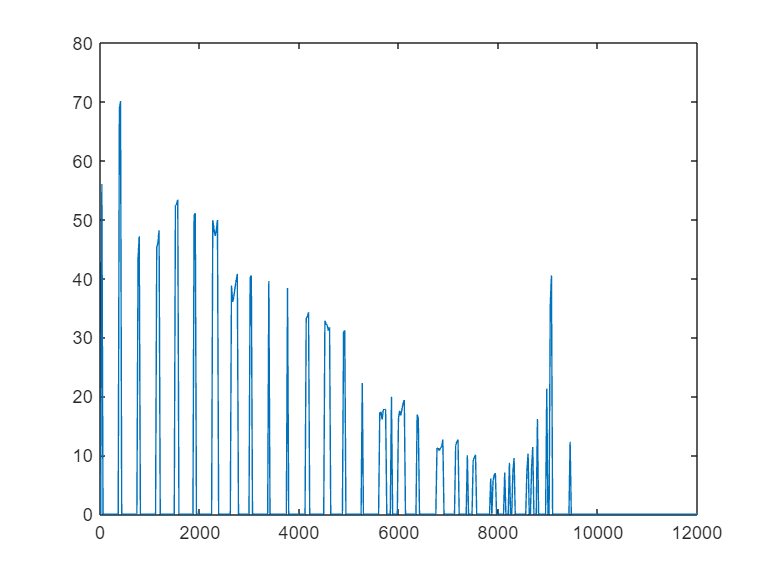

plot(half_freq,Lk_after_masking)

# Apply SPLs masking to filter bank output

ss = upsample(Signal_Spectrum,235)

ss =     0.0026         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


240000/1024

ans = 234.3750


fff = real(fftshift(ifft(Signal_Spectrum,240000)))

fff =    -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000


signal.'

ans =          0         0         0         0         0         0         0         0         0         0   -0.0021   -0.0021   -0.0066   -0.0066   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0062   -0.0063   -0.0063   -0.0061   -0.0061   -0.0060   -0.0060   -0.0060   -0.0060   -0.0060   -0.0061   -0.0061   -0.0061   -0.0061   -0.0061   -0.0061   -0.0061   -0.0061   -0.0061   -0.0062   -0.0061   -0.0061


Fs

Fs = 24000

sound(fff,Fs)
%sound(signal,Fs)